# 7.1 Optimum filters

Alexandre Rey, MSE, Ma-StatDig, 2022

clear;
rng default; % to keep same random
addpath('../functions/');
importedData = load('ex71_data.mat');

Goal: estimate one signal from another one, such that the resulting mean square error is as small as possible.

## EX 7.1: FIR Wiener - Filtering application (7.2.1)

In the filtering problem, a signal $d[n]$, whose autocorrelation is known, is to be estimated from a noise corrupted observation:$x[n] = d[n] + v[n]$

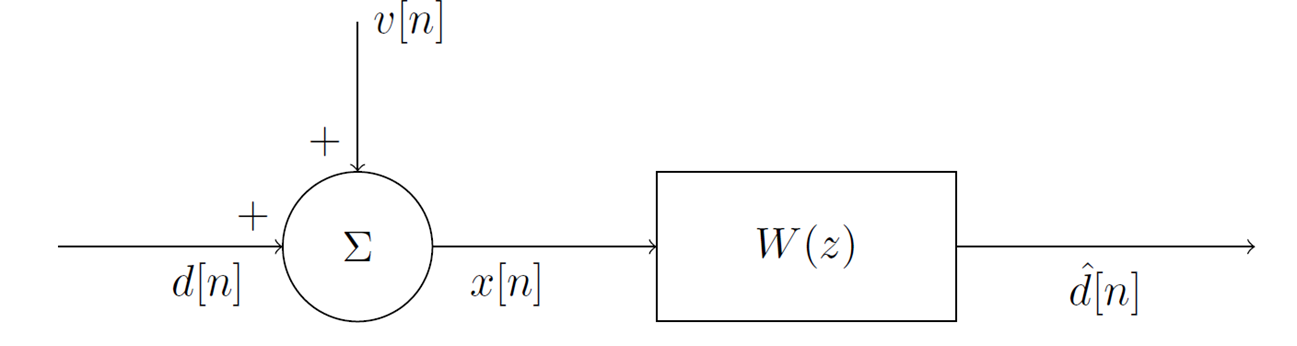

Let $d[n]$ be an AR(1) process excited by a zero mean white noise with unit variance:

$d[n] = a[1]d[n - 1] + w[n]$          where $a[1] = 0.8$


$$H\left(z\right)=\frac{1}{1-0\ldotp 8z^{-1} }$$


and suppose that $d[n]$ is observed in the presence of uncorrelated white noise $v[n]$ with variance $\sigma_v^2$. The signal $d[n]$ has a unit variance.

**The goal is to filter **$x[n]$** with Wiener filter **$W(z)$** to estimate **$d[n]$**.**

## Signals creation

### Parameters

a = [1, 0.8];
a1 = a(2);      % a[1]
Alpha = 0.8;    % 
SigmaW = 1;
SigmaV = 1;     % standard deviation of the noise v[n]
N = 500;
p = 1;

disp(table(a1, Alpha, SigmaW, SigmaV, N, p));

    a1     Alpha    SigmaW    SigmaV     N     p
    ___    _____    ______    ______    ___    _

    0.8     0.8       1         1       500    1



### Signal generation

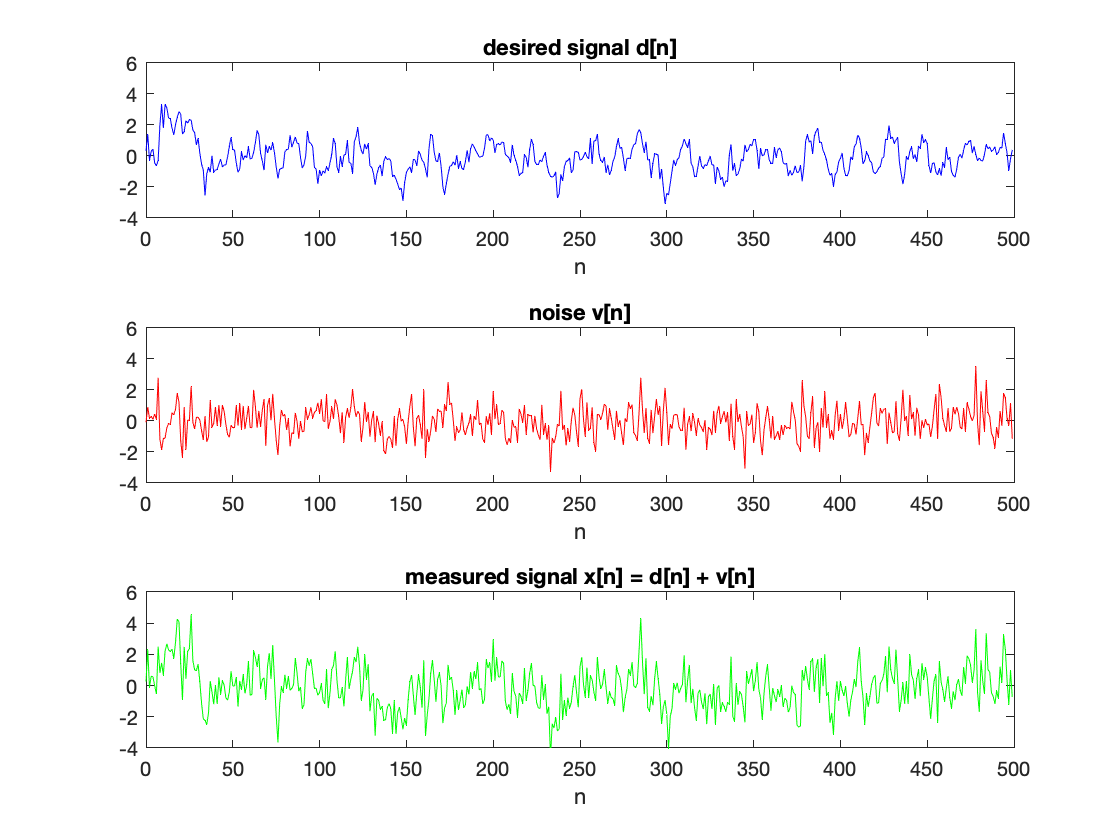

%vn = SigmaV*randn(1,N);               % noise
vn = importedData.vn;                  % to get same noise as teacher

% wn = SigmaW*randn(1,N);              % zero mean white noise
% dn = a1*filter(1, [1, -Alpha], wn);  % which excites AR(1) process
% dn = dn/std(dn);                     % dn scaling
dn = importedData.d;                   % to get same d[n] as teacher (consider the same white noise)

xn = dn+vn;                            % add noise to the output of the process

n = 0:N-1;

figure;
tiledlayout(3,1);
ax1 = nexttile;
    plot(n, dn, 'b');
    title('desired signal d[n]');
    xlabel('n');
ax2 = nexttile;
    plot(n, vn, 'r');
    title('noise v[n]');
    xlabel('n');
ax3 = nexttile;
    plot(n, xn, 'g');
    title('measured signal x[n] = d[n] + v[n]');
    xlabel('n');
linkaxes([ax1,ax2,ax3], 'xy');
%ax1.XLim=[0, N-1];
ax1.YLim=[-4, 6];

## Theoretical FIR wiener filter

### Design filter

By knowing the signal characteristics, the Wiener filter based on its theoretical statistical parameters can be designed:

By assuming that $v[n]$ is zero-mean and not correlated with $d[n]$, the Wiener-Hopf equation simplied to:


$$[R_{d} + R_{v}]w = r_{d}$$


- As the process $d[n]$ is a AR(1) the theoretical auto-correlation of the desired signal is known. For a first order Wiener filter (p=1), the theoretical autocorrelation matrix can be built:

$r_{d}[k] = \alpha^{k}$ with $\alpha = a[1] = 0.8$

         
$${\mathit{\mathbf{R}}}_d =\left\lbrack \begin{array}{cc}
r_d \left\lbrack 0\right\rbrack  & r_d \left\lbrack 1\right\rbrack \\
r_d \left\lbrack 1\right\rbrack  & r_d \left\lbrack 0\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1\; & \alpha \\
\alpha  & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1\; & 0\ldotp 8\\
0\ldotp 8 & 1
\end{array}\right\rbrack$$



$${\mathit{\mathbf{r}}}_d =\left\lbrack \begin{array}{c}
r_d \left\lbrack 0\right\rbrack \\
r_d \left\lbrack 1\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
\alpha 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
0\ldotp 8
\end{array}\right\rbrack$$
 

- As the noise as a unit variance, the theoretical autocorrelation of the noise is known:


$$r_{v}[k] = \sigma_v^2\delta[k] = \delta[k]$$



$$R_v =\left\lbrack \begin{array}{cc}
\sigma_v^2 \; & 0\\
0 & \sigma_v^2 \;
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1\; & 0\\
0 & 1
\end{array}\right\rbrack$$


- It gives the theoretical Wiener-Hopf equation

$R_x =R_d +R_v$=$\left\lbrack \left\lbrack \begin{array}{cc}
1\; & \alpha \\
\alpha  & 1
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
\sigma_v^2 \; & 0\\
0 & \sigma_v^2 \;
\end{array}\right\rbrack \right\rbrack =\left\lbrack \left\lbrack \begin{array}{cc}
1\; & 0\ldotp 8\\
0\ldotp 8 & 1
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
1\; & 0\\
0 & 1
\end{array}\right\rbrack \right\rbrack$


$$\left\lbrack \left\lbrack \begin{array}{cc}
1\; & \alpha \\
\alpha  & 1
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
\sigma_v^2 \; & 0\\
0 & \sigma_v^2 \;
\end{array}\right\rbrack \right\rbrack \left\lbrack \begin{array}{c}
w\left\lbrack 0\right\rbrack \\
w\left\lbrack 1\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
\alpha 
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{cc}
2\; & 0\ldotp 8\\
0\ldotp 8 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
w\left\lbrack 0\right\rbrack \\
w\left\lbrack 1\right\rbrack 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
0\ldotp 8
\end{array}\right\rbrack$$


- By solving that Wiener-Hopf equation, the Wiener coefficient can be estimated:


$$\left\lbrack \begin{array}{c}
w\left\lbrack 0\right\rbrack \\
w\left\lbrack 1\right\rbrack 
\end{array}\right\rbrack ={\left\lbrack \begin{array}{cc}
2\; & 0\ldotp 8\\
0\ldotp 8 & 2
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
1\\
0\ldotp 8
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\ldotp 4048\\
0\ldotp 2381
\end{array}\right\rbrack$$


- The theoretical squared norm minimum error can be determined:


$$\xi_{\min } =r_d \left\lbrack 0\right\rbrack -w\left\lbrack 0\right\rbrack r_d \left\lbrack 0\right\rbrack -w\left\lbrack 1\right\rbrack r_d \left\lbrack 1\right\rbrack =0\ldotp 4048$$


The computed values are:

% theorically
N_th = 20;
k = -N_th:N_th;                     % k
rd = a1.^k(k>=0)';                  % rd[k=0..N_th]
rv = [SigmaV^2, zeros(1, N_th)]';   % rv[k=0..N_th]

%Rd = [rd(1:p+1), flip(rd(1:p+1))];
%Rv = [rv(1:p+1), flip(rv(1:p+1))];
Rd = toeplitz(rd(1:p+1), rd(1:p+1));
Rv = toeplitz(rv(1:p+1), rv(1:p+1));

Rx = Rd + Rv;
W = Rx\rd(1:p+1);          % => W = inv(Rx)*rd;

E = rd(1) - rd(1:p+1)'*W;

disp('Rx='); disp(Rx); disp('Rv'); disp(Rv); disp('rd='); disp(rd(1:p+1)); disp('W='); disp(W); disp('E='); disp(E);

Rx=
    2.0000    0.8000
    0.8000    2.0000

Rv
     1     0
     0     1

rd=
    1.0000
    0.8000

W=
    0.4048
    0.2381

E=
    0.4048



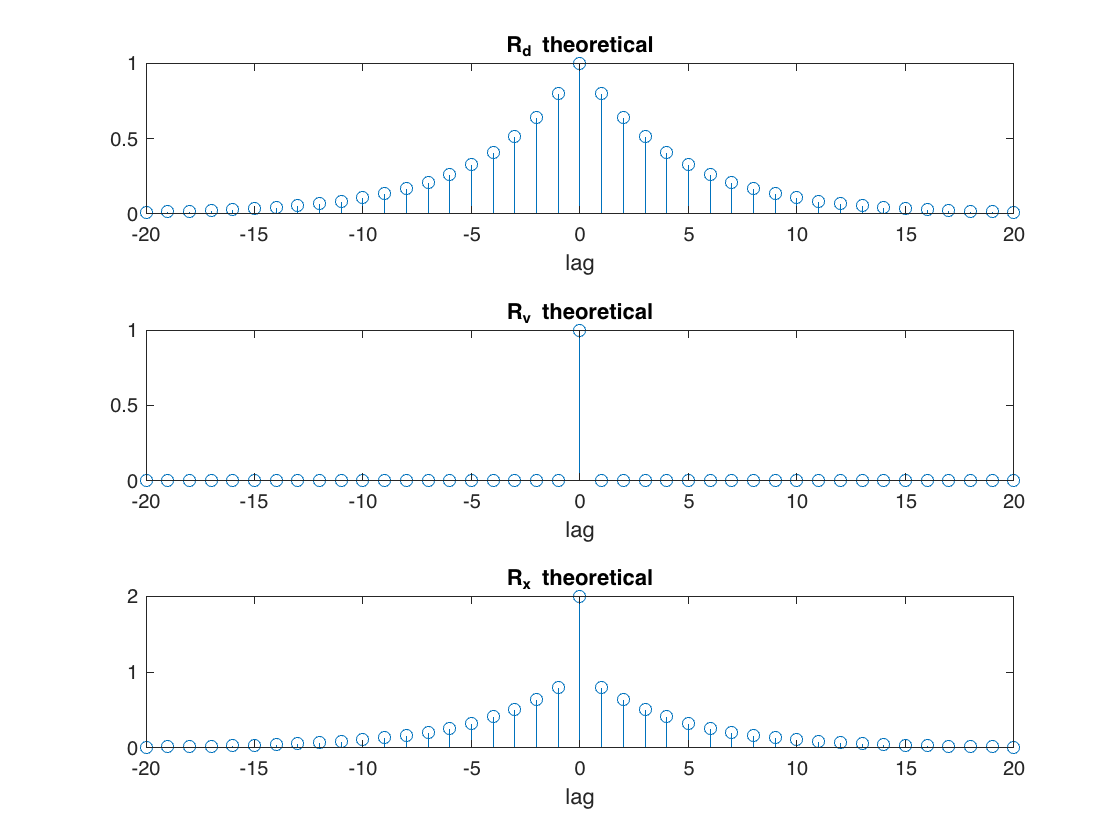

figure;
tiledlayout(3,1);
nexttile;
    stem(k, [flip(rd(2:end))', rd']);
    title('R_d theoretical');
    xlabel('lag');
nexttile;
    stem(k, [flip(rv(2:end))', rv']);
    title('R_v theoretical');
    xlabel('lag');
nexttile;
    stem(k, [flip(rd(2:end))', rd'] + [flip(rv(2:end))', rv']);
    title('R_x theoretical');
    xlabel('lag'); 

### Filter analysis

The frequency response and the zero and pole of the filter can be displayed. It creates a low pass filter.

%                b: numerator
%                |    a: denominator
%                |    |
Wtf_coef = table(W', [1, zeros(1,p)]);
Wtf_coef.Properties.VariableNames = ["b","a"];

Wtf = tf(Wtf_coef.b,Wtf_coef.a,1)

Wtf =
 
  0.4048 z + 0.2381
  -----------------
          z
 
Sample time: 1 seconds
Discrete-time transfer function.



[H, omega] = freqresp(Wtf);
[hn, t] = impz(Wtf_coef.b, Wtf_coef.a, p+1);

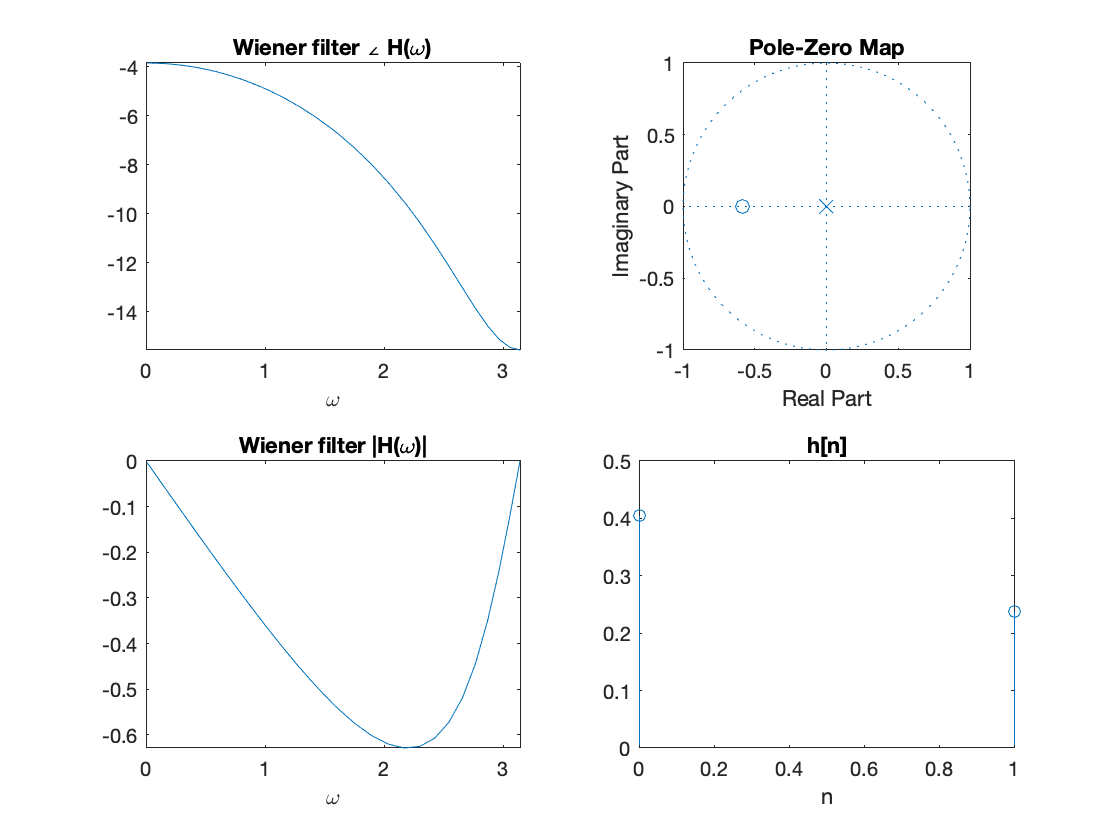

figure;
subplot(2,2,1);
    plot(omega, 20*log10(abs(H(:))));
    title('Wiener filter \angle H(\omega)');
    xlabel('\omega');
subplot(2,2,2);
    %pzmap(Wtf);
    zplane(Wtf_coef.b, Wtf_coef.a);
    title('Pole-Zero Map');
    xlim([-1 1]);
    ylim([-1 1]);
subplot(2,2,3);
    plot(omega, angle(H(:)));
    title('Wiener filter |H(\omega)|');
    xlabel('\omega');
subplot(2,2,4);
    stem(t, hn);
    title('h[n]');
    xlabel('n');

### Signal filtering

The signal can now be filtered by the Wiener filter.

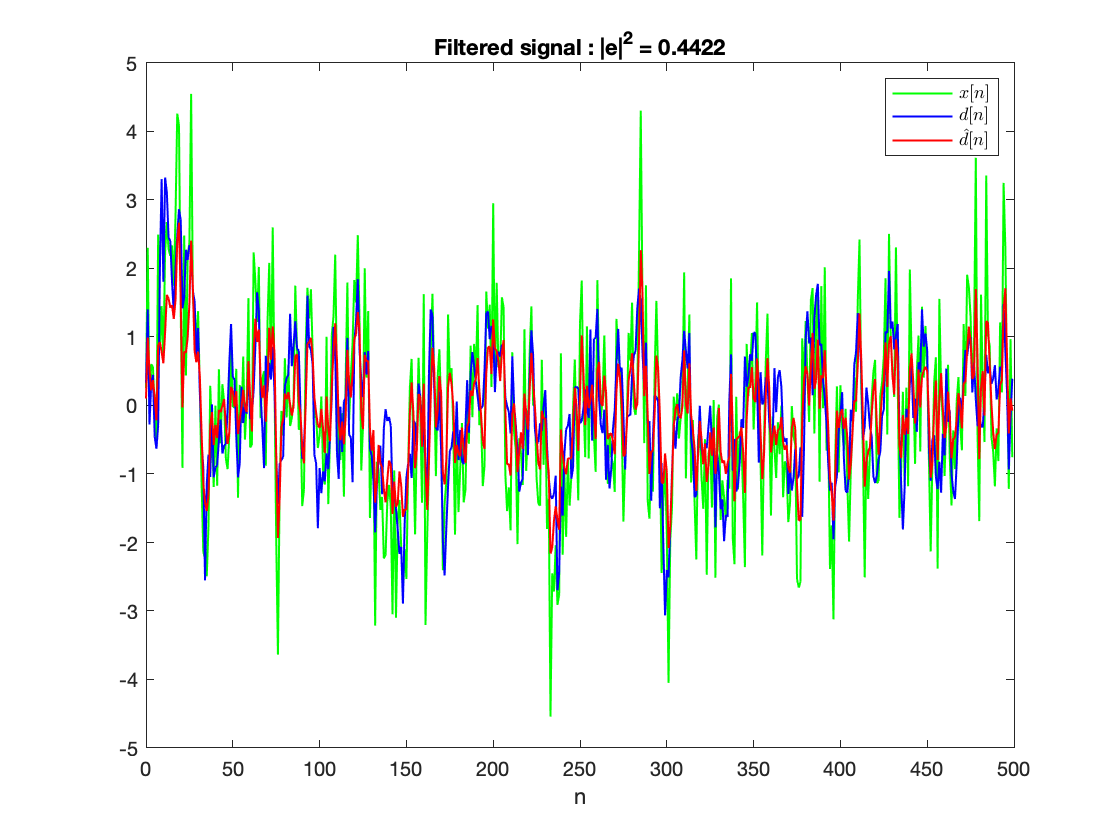

dnhat = filter(Wtf_coef.b, Wtf_coef.a, xn); % filter xn
en = mean((dn-dnhat).^2);       % mean squared error

figure
    plot(n, xn, 'g', ...
         n, dn, 'b', ...
         n, dnhat, 'r', LineWidth=1)
    title(['Filtered signal : |e|^2 = ', num2str(en)])
    legend('$x[n]$', '$d[n]$', '$\hat{d}[n]$','Interpreter','latex')
    xlabel('n')

### Signal noise ratio

The SNR can be then determined before and after filtering.

**Prior to filtering**, since $r_d \left\lbrack 0\right\rbrack =\sigma_d^2 =1$ and $r_v \left\lbrack 0\right\rbrack =\sigma_v^2 =1$, then the power in $d[n]$ is equal to the power in $v[n]$, $E\left\lbrace {\left|d\left\lbrack n\right\rbrack \right|}^2 \right\rbrace =E\left\lbrace {\left|v\left\lbrack n\right\rbrack \right|}^2 \right\rbrace =1$, and the signal to noise ratio is:

$\textrm{SNR}=10\textrm{log10}\left(\frac{E\left\lbrace {\left|d\left\lbrack n\right\rbrack \right|}^2 \right\rbrace }{E\left\lbrace {\left|v\left\lbrack n\right\rbrack \right|}^2 \right\rbrace }\right)=0$ dB

**After filtering**, the power in the signal can be estimated as follow:


$$E\left\lbrace {\left|d^{\prime } \left\lbrack n\right\rbrack \right|}^2 \right\rbrace ={\mathit{\mathbf{w}}}^T {\mathit{\mathbf{R}}}_d \mathit{\mathbf{w}}$$



$$E\left\lbrace {\left|v^{\prime } \left\lbrack n\right\rbrack \right|}^2 \right\rbrace ={\mathit{\mathbf{w}}}^T {\mathit{\mathbf{R}}}_v \mathit{\mathbf{w}}$$


$\textrm{SNR}=10\textrm{log10}\left(\frac{E\left\lbrace {\left|d^{\prime } \left\lbrack n\right\rbrack \right|}^2 \right\rbrace }{E\left\lbrace {\left|v^{\prime } \left\lbrack n\right\rbrack \right|}^2 \right\rbrace }\right)=2\ldotp 3$ dB

Then the Wiener filter increases the SNR by more than 2dB.

% mean(dn.^2)=1, mean(vn.^2)=0.9897 (should be theorically = 1 but length
% of the signal isn't infinite)
SNRbeforeFilt = 10*log10(mean(dn.^2)/mean(vn.^2)); % dB
disp(['SNRbeforeFilt = ', num2str(SNRbeforeFilt), ' dB']);

SNRbeforeFilt = 0.044882 dB


SNRafterFilt  = 10*log10( (W'*Rd*W) / (W'*Rv*W) ); % dB
disp(['SNRafterFilt = ', num2str(SNRafterFilt), ' dB']);

SNRafterFilt = 2.3025 dB


## Estimated Wiener filter

### Estimated autocorrelation

The previous part was using the theoretical autocorrelation of the desired signal and of the noise. In practice, most of the time this has to be estimated from the signal.

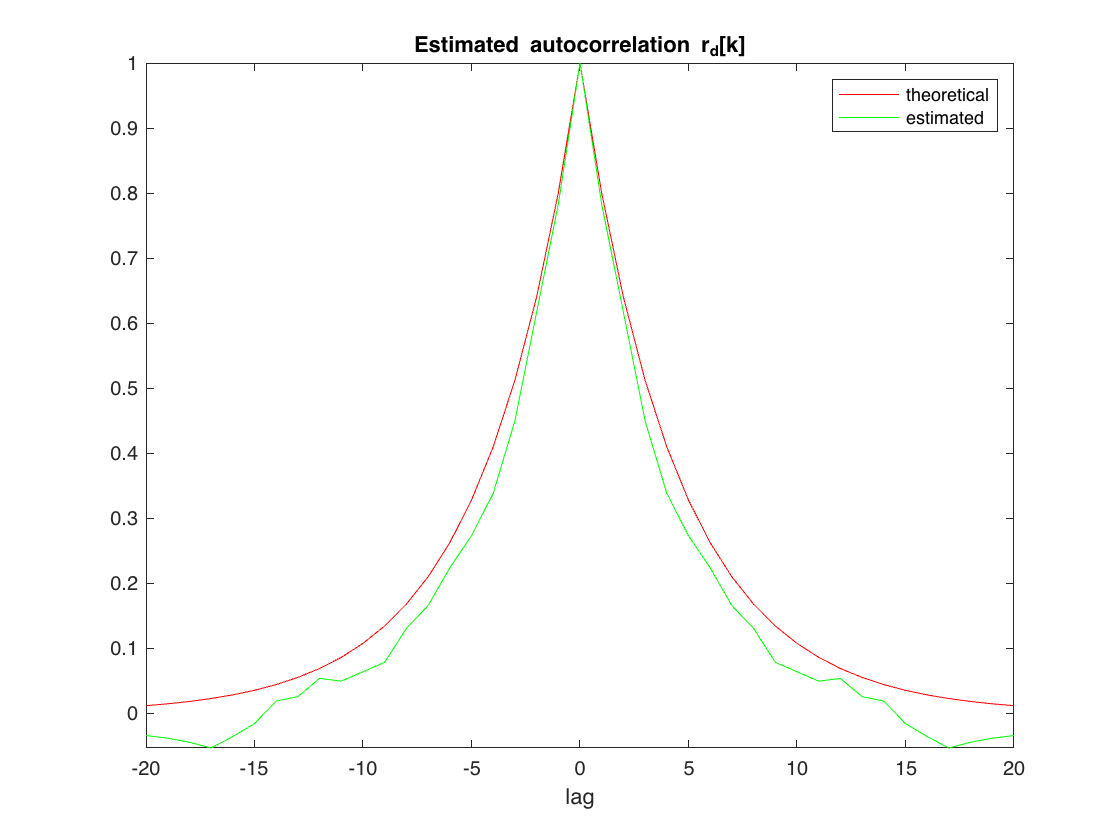

r_d_d = xcorr(dn, dn', N_th, 'biased')'; %r_d,d[k]
r_x_x = xcorr(xn, xn', N_th, 'biased')'; %r_x,x[k]

figure;
    plot(k, [flip(rd(2:end))', rd'], 'r', ...
         k, r_d_d, 'g');
    title('Estimated autocorrelation r_d[k]');
    legend('theoretical', 'estimated');
    xlabel('lag');
    axis tight;

### Wiener filter design

By using the estimated autocorrelation, the wiener filter can be designed using the same calculation than before.

On low order filter, the estimation and the theoretical gives very similar result. This is because the estimated autocorrelation is very close to the theoretical. The difference will increase with high filter order (p>1).

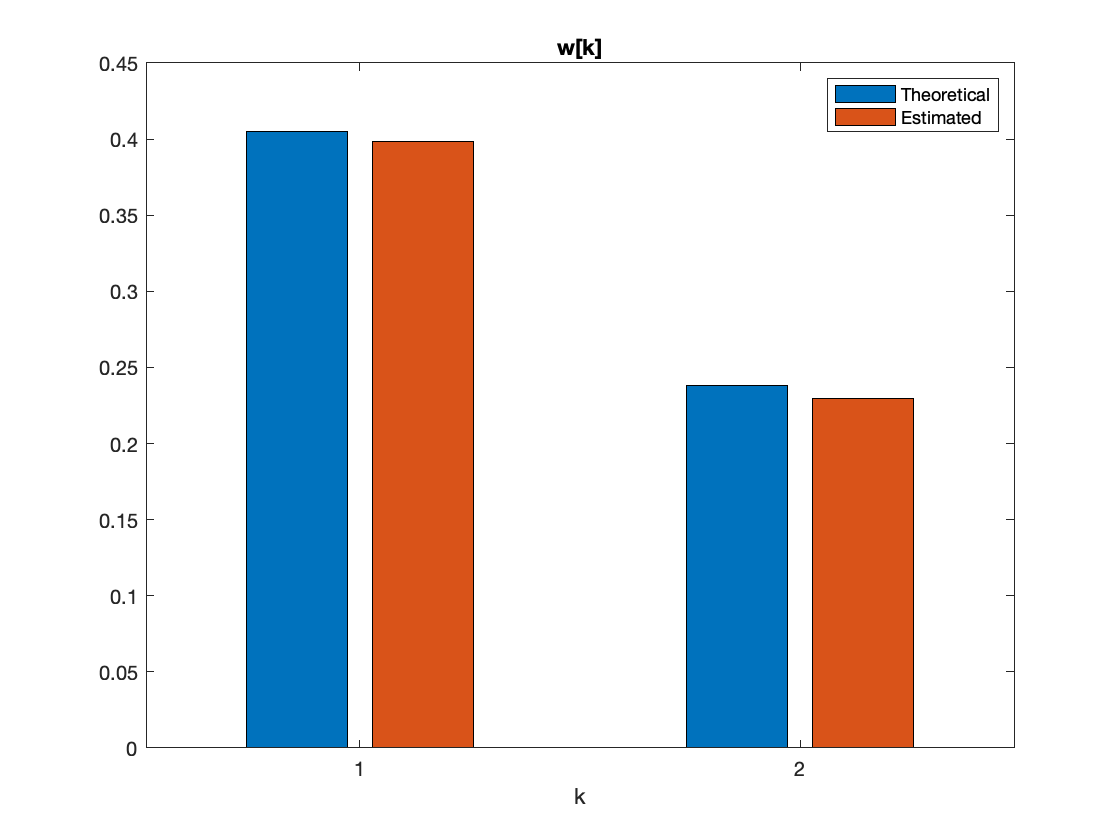

% raw method
%R_x_x = [r_x_x(k>=0 & k<=p), flip(r_x_x(k>=0 & k<=p))];
% better, auto adapt with p
R_x_x = toeplitz(r_x_x(k>=0 & k<=p), r_x_x(k>=0 & k<=p));
r_d_x = xcorr(dn, xn', N_th, 'biased')';
r_v_x = xcorr(dn, xn', N_th, 'biased')';
W_r = R_x_x \ r_d_x(k>=0 & k<=p);

figure;
    bar([W, W_r]);
    legend('Theoretical', 'Estimated');
    title('w[k]');
    xlabel('k');

### Filter analysis

The frequency response and the zero and pole of the filter can be displayed. It creates a low pass filter.

%                  b: numerator
%                  |      a: denominator
%                  |      |
Wtf_coef_r = table(W_r', [1, zeros(1,p)]);
Wtf_coef_r.Properties.VariableNames = ["b","a"];

Wtf_r = tf(Wtf_coef_r.b, Wtf_coef_r.a, 1)

Wtf_r =
 
  0.3985 z + 0.2293
  -----------------
          z
 
Sample time: 1 seconds
Discrete-time transfer function.



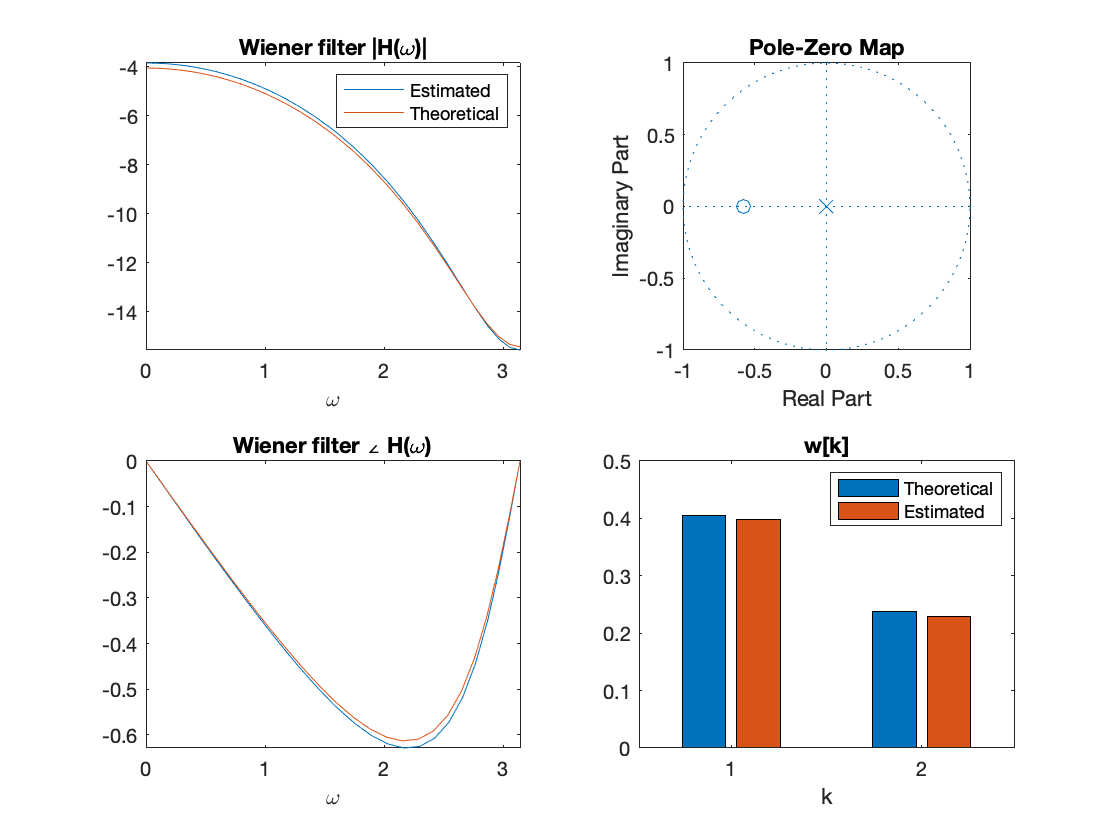

[H_r, omega_r] = freqresp(Wtf_r);

figure;
subplot(2,2,1);
    plot(omega, 20*log10(abs(H(:))), ...
         omega_r, 20*log10(abs(H_r(:))) );
    title('Wiener filter |H(\omega)|');
    legend('Estimated', 'Theoretical');
    xlabel('\omega');
subplot(2,2,2);
    %pzmap(Wtf_r);
    zplane(Wtf_coef_r.b, Wtf_coef_r.a);
    title('Pole-Zero Map');
    xlim([-1 1]);
    ylim([-1 1]);
subplot(2,2,3);
    plot(omega, angle(H(:)), ...
         omega_r, angle(H_r(:)));
    title('Wiener filter \angle H(\omega)');
    xlabel('\omega');
subplot(2,2,4);
    bar([W, W_r]);
    legend('Theoretical', 'Estimated');
    title('w[k]');
    xlabel('k');

### Signal filtering

The signal can now be filtered by the Wiener filter.

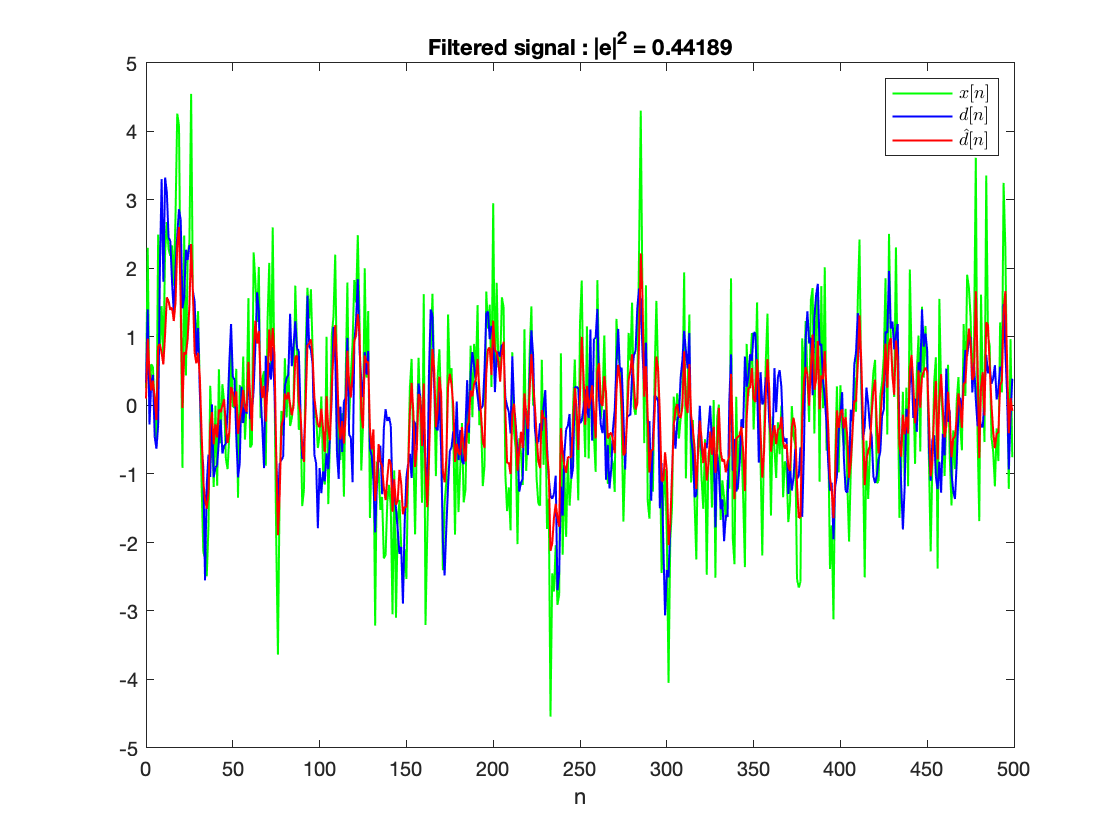

dnhat_r = filter(Wtf_coef_r.b, Wtf_coef_r.a, xn); % filter xn
en_r = mean((dn-dnhat_r).^2);       % mean squared error
figure
    plot(n, xn, 'g', ...
         n, dn, 'b', ...
         n, dnhat_r, 'r', LineWidth=1)
    title(['Filtered signal : |e|^2 = ', num2str(en_r)])
    legend('$x[n]$', '$d[n]$', '$\hat{d}[n]$','Interpreter','latex')
    xlabel('n')

## Multi P

Let's observe the SNR if we increase the filter order. It must be done with the theorical values of the signals.

Because of the non-linear phase of the Wiener FIR filter, the error signal can not be computed as **d-y. **There is a synchronisation problem. The SNR gain can not be computed as $10\textrm{log10}\left(\frac{\|\mathit{\mathbf{d}}\|}{\|\mathit{\mathbf{d}}-\mathit{\mathbf{y}}\|}\right)$. When $p$ increases, the SNR gain increases but$10\textrm{log10}\left(\frac{\|\mathit{\mathbf{d}}\|}{\|\mathit{\mathbf{d}}-\mathit{\mathbf{y}}\|}\right)$increases and then decreases ! Do not use it !

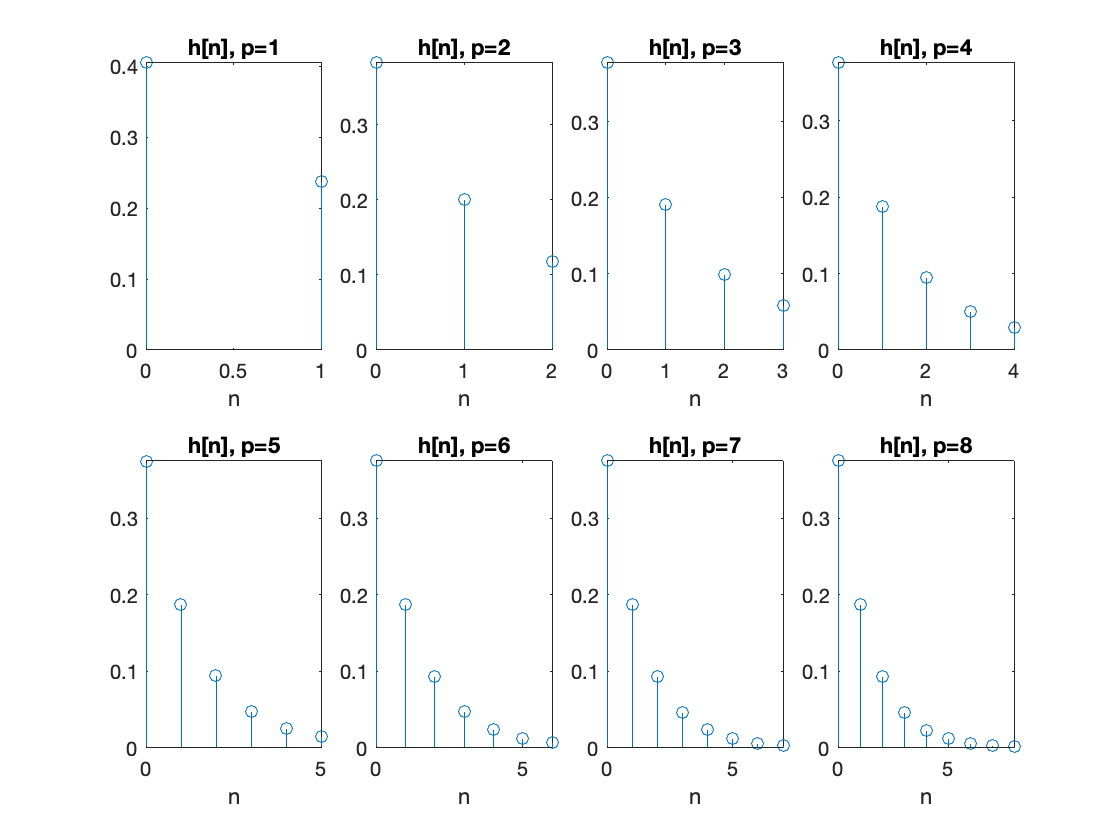

p_max = 8;
    
SNGain_wr = zeros(1, p_max); % uncorrect method
SNGAIN_tr = zeros(1, p_max); % correct method

figure;
for p=1:p_max
    
    % compute filter coef of order p
    Rd = toeplitz(rd(1:p+1), rd(1:p+1));
    Rv = toeplitz(rv(1:p+1), rv(1:p+1));
    Rx = Rd + Rv;

    W = Rx \ rd(1:p+1);
    Wtf_coef = table(W', [1, zeros(1,p)]);
    Wtf_coef.Properties.VariableNames = ["b","a"];

    [hn, t] = impz(Wtf_coef.b, Wtf_coef.a, p+1);
    
    % display impulse response
    subplot(2,4,p);
    stem(t, hn);
    title(['h[n], p=' num2str(p)]);
    xlabel('n');
    axis tight;
    
    % compute SNR
    dhat = filter(Wtf_coef.b, Wtf_coef.a, xn); % filter signal
    SNGain_wr(p) = 10*log10(norm(dn) / norm(dn-dhat));
    SNGAIN_tr(p) = 10*log10(W'*Rd*W / (W'*Rv*W));
end

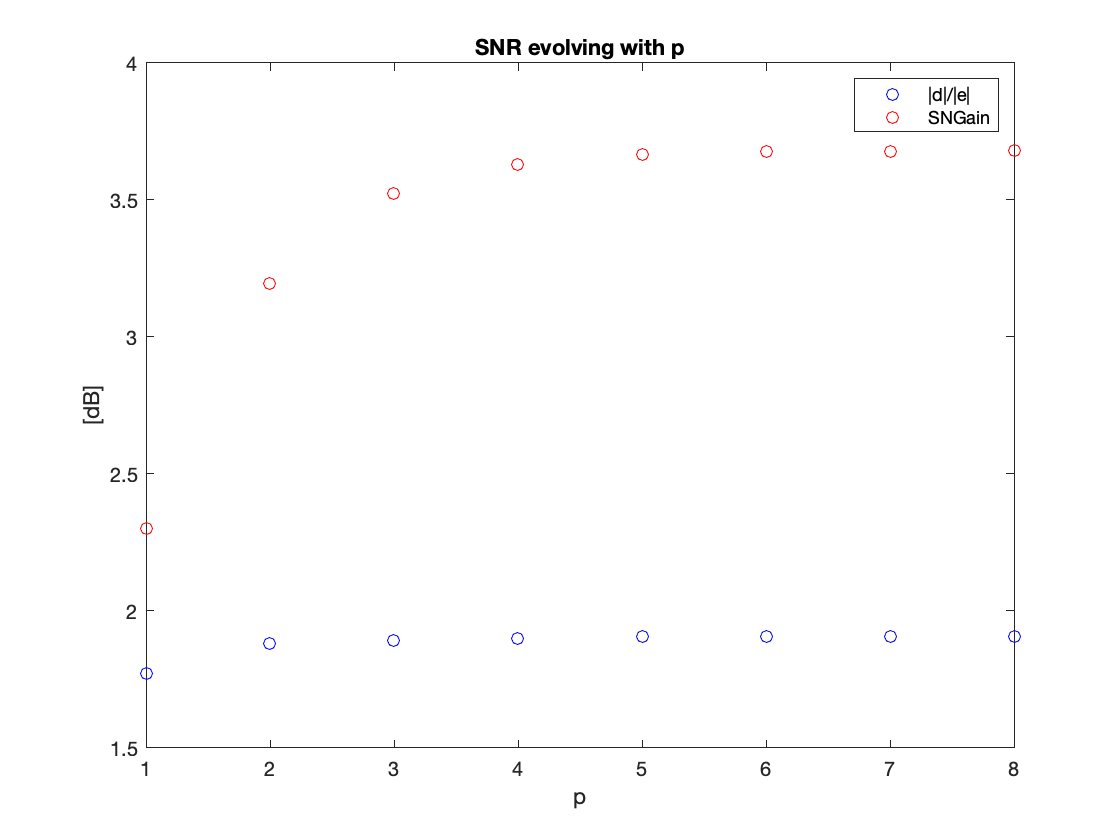

figure;
    plot(1:p_max, SNGain_wr, 'ob', ...
         1:p_max, SNGAIN_tr, 'or');
    title('SNR evolving with p');
    legend('|d|/|e|', 'SNGain');
    xlabel('p');
    ylabel('[dB]');